## Solución numérica de modelo SIR

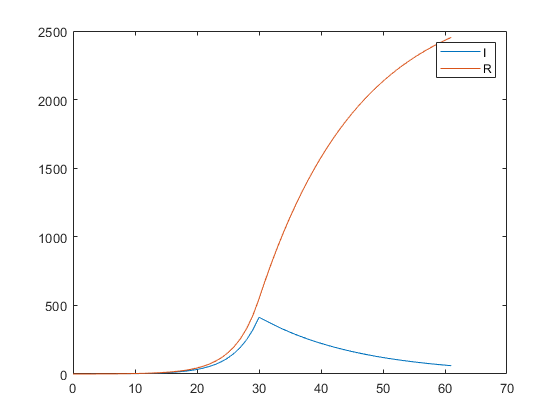

X0 = [109918558; 0.2173231; 0];

model = ode45(@fun, [0 61], X0);

t = 0:61;
X = deval(model,t);

S = X(1, :);
I = X(2, :);
R = X(3, :);

plot(t, I)
hold on
plot(t, R)
hold off
legend('I','R')


A = [t', X'];
writematrix(A, "data/simulated_SIR.csv")

### Función de evaluación SIR

function dXdt = fun(t, X)
    kappa_1 = 5.322383e-09;
    kappa_2 = 2.468628e-09;
    mu = 1/3;
    
    S = X(1);
    I = X(2);
    R = X(3);
    
    if t <= 30
        kappa = kappa_1;
    else
        kappa = kappa_2;
    end
    
    dSdt = -kappa*S*I;
    dIdt = kappa*S*I - mu*I;
    dRdt = mu*I; 
    
    dXdt = [dSdt; dIdt; dRdt];
end